clear
clc
close all
addpath('14-Oct-2022_Power_Stroke_Flipper_Results\')
load("14-Oct-2022_results_PowerStroke.mat")
results_1=results;
addpath('07-Oct-2022_Power_Stroke_Flipper_Results\')
load("07-Oct-2022_results_PowerStroke.mat")
results_2=results;

period=[1.75,2.25];
y_amp=[-60, -75, -90]*-1;
roll_pow_ang=[-90,-75,-60,-55,-50,-45,-40,-35,-30,-15,0]*-1;
%roll_pow_ang_settings=[0];
Flow_Speed=[0,28,70];
%%
% Loop order Flow, Speed, Yaw, Roll

num_experiments=length(results_1.data)+length(results_2.data);
force_scale=2.22;
j=1;
for i=67:num_experiments
    if i <= length(results_1.data)
        zeros=results_1.zeros(i).zeros;
        data=results_1.data(i).data;

        filtered_data=Data_Filters(data);
        zeroed_data=filtered_data-mean(zeros(500:1000,:));
        thr(j,:)=zeroed_data(:,1)*force_scale;
        lift1(j,:)=zeroed_data(:,2)*force_scale;
        ard(j,:)=filtered_data(:,3);
        params(j,:)=abs(results_1.parameters(i).parameters);

    else
        i=i-length(results_1.data);
        zeros=results_2.zeros(i).zeros;
        data=results_2.data(i).data;
        filtered_data=Data_Filters(data);
        zeroed_data=filtered_data-mean(zeros(500:1000,:));
        thr(j,:)=zeroed_data(:,1)*force_scale;
        lift1(j,:)=zeroed_data(:,2)*force_scale;
        ard(j,:)=data(:,3);
        params(j,:)=abs(results_2.parameters(i).parameters);
    end
    j=j+1;
end

num_experiments=length(params);


%% Fix arduino signal by bounding it

for i=1:num_experiments
    for j=1:length(ard)
        if ard(i,j)<2
            ard(i,j)=1.5;
        end
        if ard(i,j) >= 2
            ard(i,j)=10;
        end

    end

end


%% Align Traces
first_skip=700;
for k=1:66
    j=1;
    zz=1;

    mat=ard(k,:);
    for i=first_skip:length(mat)-1
        p1=mat(i);
        p2=mat(i+1);
        if j==1
            if abs(p1-p2)>8
                true_index(k,j)=i;
                j=j+1;
            end
        else
            if abs(p1-p2)>8 && abs(true_index(k,j-1)-i) > 5
                true_index(k,j)=i;
                j=j+1;
            end

        end


    end

end


for k=67:num_experiments
    j=1;
    zz=1;

    mat=ard(k,:);
    for i=first_skip:length(mat)-1
        p1=mat(i);
        p2=mat(i+1);
        if abs(p1-p2)>2
            true_index(k,j)=i;
            j=j+1;
        end


    end
end

%%
set=1;
set_length=length(roll_pow_ang);
extra_points2=50;
jj=1;
for a=Flow_Speed
    for k=period
        for kk=y_amp
            ii=1;

            for i=set:set+set_length-1
                clear traces_thr thrust traces_lift lift2

                z=1;

                for j=1:2:10

                    if j==1
                        trace_length=true_index(i,j+1)-true_index(i,j);
                        extra_points=round(trace_length/5);
                        trace_length=trace_length-extra_points+extra_points2;
                        thrust(z)=mean(thr(i,true_index(i,j):true_index(i,j)+trace_length-1));
                        traces_thr(z,:)=thr(i,true_index(i,j):true_index(i,j)+trace_length-1);
                        lift2(z)=mean(lift1(i,true_index(i,j):true_index(i,j)+trace_length-1));
                        traces_lift(z,:)=lift1(i,true_index(i,j):true_index(i,j)+trace_length-1);
                    else
                        thrust(z)=mean(thr(i,true_index(i,j):(true_index(i,j)+trace_length-1)));
                        traces_thr(z,:)=thr(i,true_index(i,j):true_index(i,j)+trace_length-1);
                        lift2(z)=mean(lift1(i,true_index(i,j):true_index(i,j)+trace_length-1));
                        traces_lift(z,:)=lift1(i,true_index(i,j):true_index(i,j)+trace_length-1);
                        % hold on
                        % plot(traces_thr(z,:))
                        % hold off
                    end
                    z=z+1;
                end
                mean_thr_struct(jj,ii).period=mean(thrust);
                std_error_thr_struct(jj,ii).period=std(thrust);
                mean_traces_thr(jj,ii).period=mean(traces_thr);
                std_traces_thr(jj,ii).period=std(traces_thr)/sqrt(4);

                mean_lift_struct(jj,ii).period=mean(lift2);
                std_error_lift_struct(jj,ii).period=std(lift2);
                mean_traces_lift(jj,ii).period=mean(traces_lift);
                std_traces_lift(jj,ii).period=std(traces_lift)/sqrt(4);

                ii=ii+1;

            end

            % figure
            % plot(roll_pow_ang,[mean_lift_struct(jj,:).period])
            jj=jj+1;
            set=set+set_length;
        end

    end


end

%% unpack structs
z=1;
for j=1:18
    for i=1:11
        mean_thrust(j,i)=mean_thr_struct(j,i).period;
        std_thrust(j,i)=std_error_thr_struct(j,i).period;

        thr_traces(j,i)=mean_traces_thr(j,i);
        thr_traces_std(z)=std_traces_thr(j,i);

        mean_lift(j,i)=mean_lift_struct(j,i).period;
        std_lift(z)=std_error_lift_struct(j,i).period;
        lift_traces(j,i)=mean_traces_lift(j,i);
        lift_traces_std(z)=std_traces_lift(j,i);
        z=z+1;
    end
end


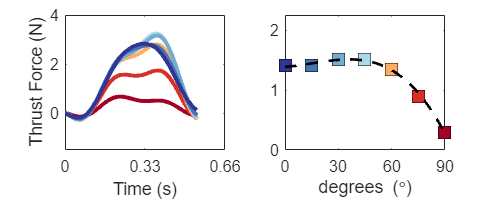

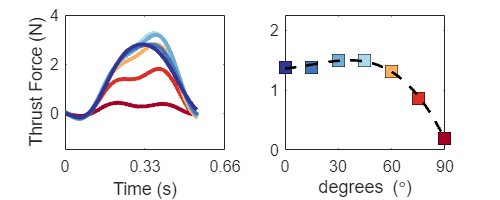

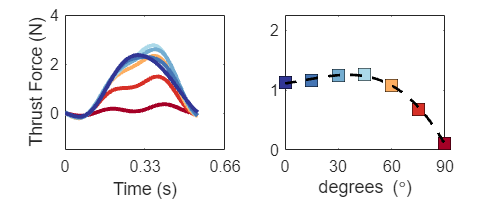

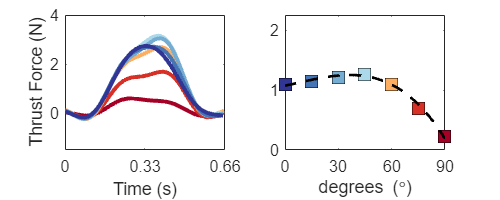

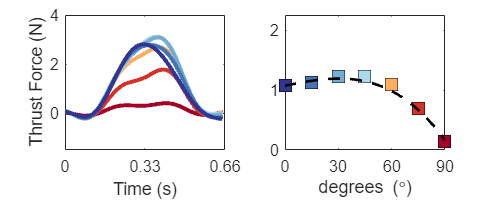

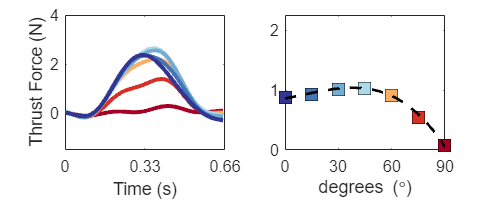

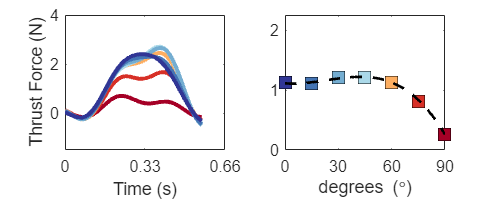

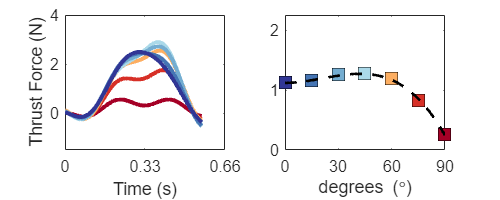


%% Plot Trace Comparison for Flow Speed
close all
clc
colors={[165,0,38]/255,...
    [215,48,39]/255,...
    [253,174,97]/255,...
    [171,217,233]/255,...
    [116,173,209]/255,...
    [69,117,180]/255,...
    [49,54,149]/255,...
    [255,127,0]/255,...
    [202,178,214]/255,...
    [106,61,154]/255,...
    [177,89,40]/255};

index=[1,2,3,6,9,10,11];


for z=1:18
    figure('Renderer', 'painters', 'Position', [10 10 500 200])
    j=1;

    for i=index
        hold on
        subplot(1,2,1)
        period=length(thr_traces(z,i).period)/250;
        x=linspace(0,period,length(thr_traces(z,i).period));
        plot(x,thr_traces(z,i).period,'color',colors{j},'LineWidth',3)

        hold off
        xlim([0 .66])
        ylim([-1.5 4])
        ylabel('Thrust Force (N)')
        xlabel('Time (s)')
        xticks(0:.33:.66)
        xticklabels({'0','0.33','0.66'})
        ax=gca;
        ax.FontSize=12;

        j=j+1;
    end
    j=1;
    for i=index
        hold on
        subplot(1,2,2)
        plot(roll_pow_ang(i),mean_thrust(z,i),'s',...
            'MarkerEdgeColor','k','MarkerFaceColor',colors{j},'MarkerSize',12)

        hold off
        j=j+1;
    end
    x1=linspace(0,max(roll_pow_ang));
    p1=polyfit(roll_pow_ang,mean_thrust(z,:),3);
    y1=polyval(p1,x1);
    hold on
    subplot(1,2,2)
    plot(x1,y1,'--k','LineWidth',2)
    hold off
    xlim([0 90])
    ylim([0 2.25])
    xlabel('degrees (\circ)')
    xticks(0:30:90)
    xticklabels({'0','30','60','90'})
    ax=gca;
    ax.FontSize=12;
end

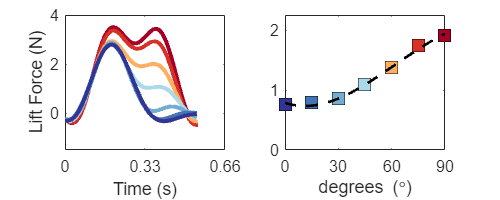

*********** 1.000000 ************** 


The PERIOD is 1.750000


The YAW is 60.000000


The FLOW is 0.000000


--------------------------------


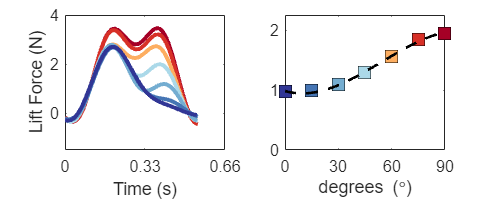

*********** 2.000000 ************** 


The PERIOD is 1.750000


The YAW is 75.000000


The FLOW is 0.000000


--------------------------------


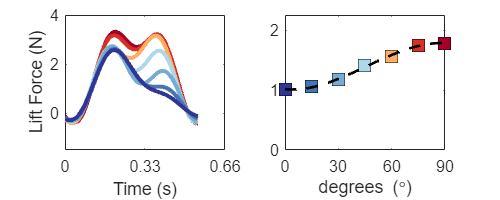

*********** 3.000000 ************** 


The PERIOD is 1.750000


The YAW is 90.000000


The FLOW is 0.000000


--------------------------------


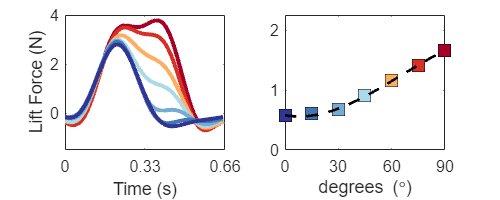

*********** 4.000000 ************** 


The PERIOD is 2.250000


The YAW is 60.000000


The FLOW is 0.000000


--------------------------------


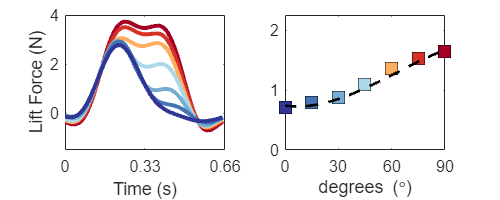

*********** 5.000000 ************** 


The PERIOD is 2.250000


The YAW is 75.000000


The FLOW is 0.000000


--------------------------------


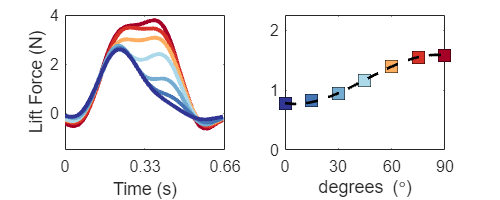

*********** 6.000000 ************** 


The PERIOD is 2.250000


The YAW is 90.000000


The FLOW is 0.000000


--------------------------------


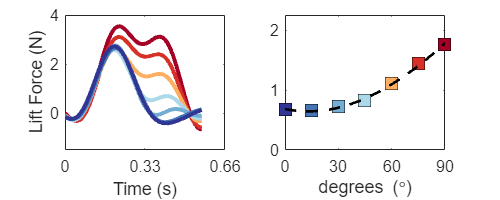

*********** 7.000000 ************** 


The PERIOD is 1.750000


The YAW is 60.000000


The FLOW is 28.000000


--------------------------------


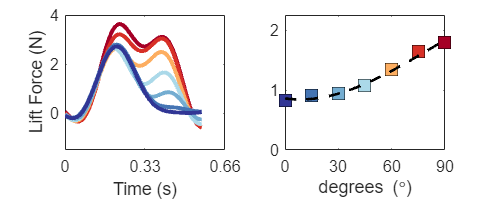

*********** 8.000000 ************** 


The PERIOD is 1.750000


The YAW is 75.000000


The FLOW is 28.000000


--------------------------------


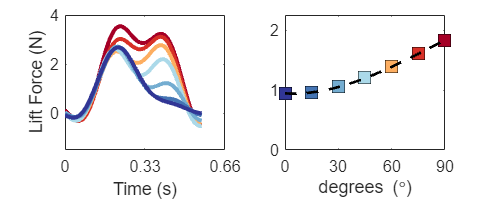

*********** 9.000000 ************** 


The PERIOD is 1.750000


The YAW is 90.000000


The FLOW is 28.000000


--------------------------------


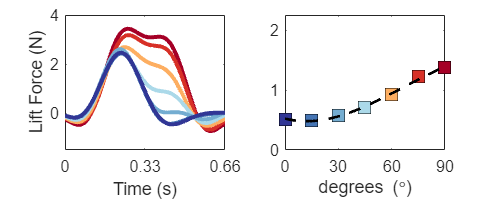

*********** 10.000000 ************** 


The PERIOD is 2.250000


The YAW is 60.000000


The FLOW is 28.000000


--------------------------------


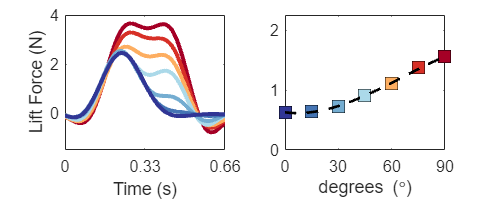

*********** 11.000000 ************** 


The PERIOD is 2.250000


The YAW is 75.000000


The FLOW is 28.000000


--------------------------------


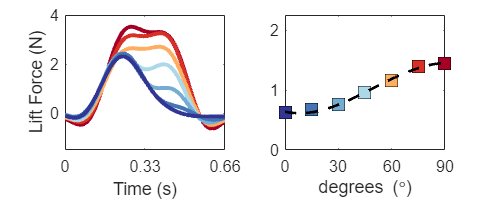

*********** 12.000000 ************** 


The PERIOD is 2.250000


The YAW is 90.000000


The FLOW is 28.000000


--------------------------------


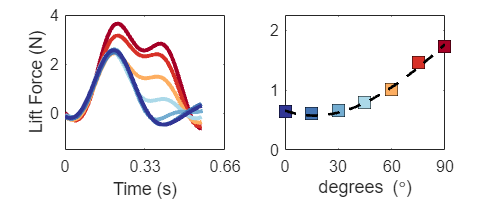

*********** 13.000000 ************** 


The PERIOD is 1.750000


The YAW is 60.000000


The FLOW is 70.000000


--------------------------------


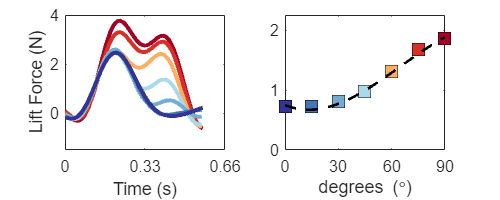

*********** 14.000000 ************** 


The PERIOD is 1.750000


The YAW is 75.000000


The FLOW is 70.000000


--------------------------------


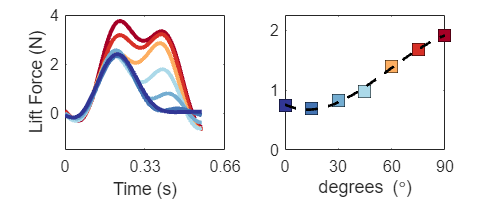

*********** 15.000000 ************** 


The PERIOD is 1.750000


The YAW is 90.000000


The FLOW is 70.000000


--------------------------------


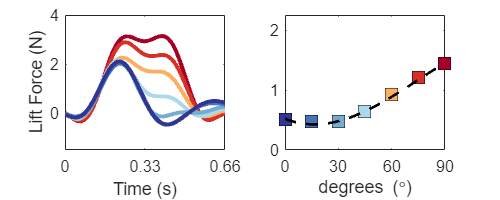

*********** 16.000000 ************** 


The PERIOD is 2.250000


The YAW is 60.000000


The FLOW is 70.000000


--------------------------------


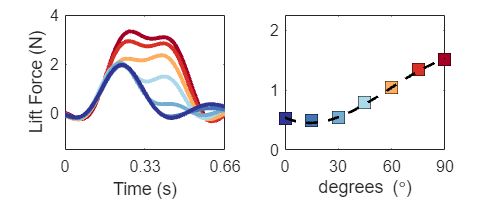

*********** 17.000000 ************** 


The PERIOD is 2.250000


The YAW is 75.000000


The FLOW is 70.000000


--------------------------------


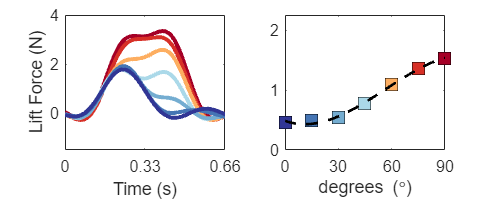

*********** 18.000000 ************** 


The PERIOD is 2.250000


The YAW is 90.000000


The FLOW is 70.000000


--------------------------------






for z=1:18
    figure('Renderer', 'painters', 'Position', [10 10 500 200])
    j=1;

    for i=index
        hold on
        subplot(1,2,1)
        period=length(lift_traces(z,i).period)/250;
        x=linspace(0,period,length(lift_traces(z,i).period));
        plot(x,lift_traces(z,i).period,'color',colors{j},'LineWidth',3)

        hold off
        xlim([0 .66])
        ylim([-1.5 4])
        ylabel('Lift Force (N)')

        xlabel('Time (s)')
        xticks(0:.33:.66)
        xticklabels({'0','0.33','0.66'})
        ax=gca;
        ax.FontSize=12;
        j=j+1;
    end
    j=1;

    for i=index
        hold on
        subplot(1,2,2)
        plot(roll_pow_ang(i),mean_lift(z,i),'s',...
            'MarkerEdgeColor','k','MarkerFaceColor',colors{j},'MarkerSize',12)

        hold off
        j=j+1;
        xlim([0 90])
        ylim([0 2.25])
        xlabel('degrees (\circ)')
        xticks(0:30:90)
        xticklabels({'0','30','60','90'})
        ax=gca;
        ax.FontSize=12;

    end
    x1=linspace(0,max(roll_pow_ang));
    p1=polyfit(roll_pow_ang,mean_lift(z,:),3);
    y1=polyval(p1,x1);
    hold on
    subplot(1,2,2)
    plot(x1,y1,'--k','LineWidth',2)
    hold off

    ind = z*11 - 6;
    fprintf('*********** %f ************** \n', z);
    fprintf('The PERIOD is %f\n', params(ind,1));
    fprintf('The YAW is %f\n', params(ind,2));
    fprintf('The FLOW is %f\n', params(ind,4));
    fprintf('--------------------------------\n');

end


% %% Custom Graphs
% 
% colors={[165,0,38]/255,...
%     [215,48,39]/255,...
%     [253,174,97]/255,...
%     [171,217,233]/255,...
%     [116,173,209]/255,...
%     [69,117,180]/255,...
%     [49,54,149]/255,...
%     [255,127,0]/255,...
%     [202,178,214]/255,...
%     [106,61,154]/255,...
%     [177,89,40]/255};
% 
% Marker_Style={'o','d','^'};
% Line_Style={'--',':'};
% 
% index=[1,2,3,6,9,10,11];
% 
% figure('Renderer', 'painters', 'Position', [10 10 500 200])
% for z=1:6
% 
%     j=1;
% 
%     for i=index
%         hold on
%         subplot(3,3,z)
%         period=length(thr_traces(z,i).period)/250;
%         x=linspace(0,period,length(thr_traces(z,i).period));
%         plot(x,thr_traces(z,i).period,'color',colors{j},'LineWidth',4)
% 
%         hold off
%         if z==1 || z==4
%             ylabel('Lift Force (N)')
%         end
%         xlim([0 .66])
%         ylim([-1.5 4])
%         if z==4 || z==5 || z==6
%             xlabel('Time (s)')
%         end
% 
%         xticks(0:.33:.66)
%         xticklabels({'0','0.33','0.66'})
%         ax=gca;
%         ax.FontSize=12;
% 
%         j=j+1;
%     end
%     j=1;
% 
%     x1=linspace(0,max(roll_pow_ang));
%     p1=polyfit(roll_pow_ang,mean_thrust(z,:),3);
%     y1=polyval(p1,x1);
% 
%     zz=ceil(z/3);
%     hold on
%     subplot(3,3,7:9)
%     plot(x1,y1,strcat(Line_Style{zz},'k'),'LineWidth',4)
%     hold off
%     xlim([0 90])
%     ylim([0 2.25])
%     xlabel('degrees (\circ)')
%     ylabel('Lift Force (N)')
%     xticks(0:30:90)
%     xticklabels({'0','30','60','90'})
%     zz=z;
%     if z > 3
%         zz=z-3;
%     end
%     for i=index
%         hold on
%         subplot(3,3,7:9)
%         plot(roll_pow_ang(i),mean_thrust(z,i),Marker_Style{zz},...
%             'MarkerEdgeColor','k','MarkerFaceColor',colors{j},'MarkerSize',5)
% 
%         hold off
%         j=j+1;
%     end
%     ax=gca;
%     ax.FontSize=12;
% end
